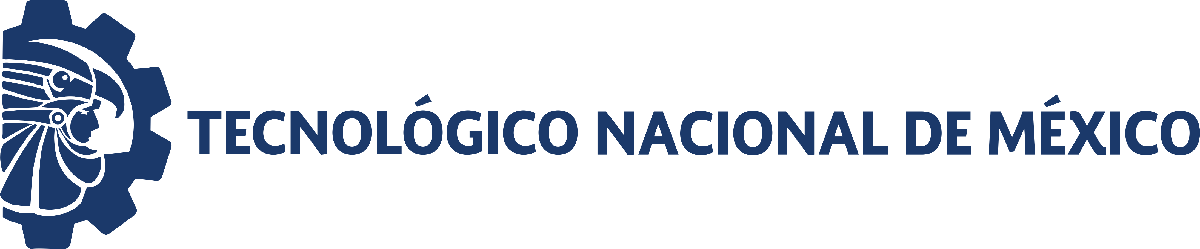                                 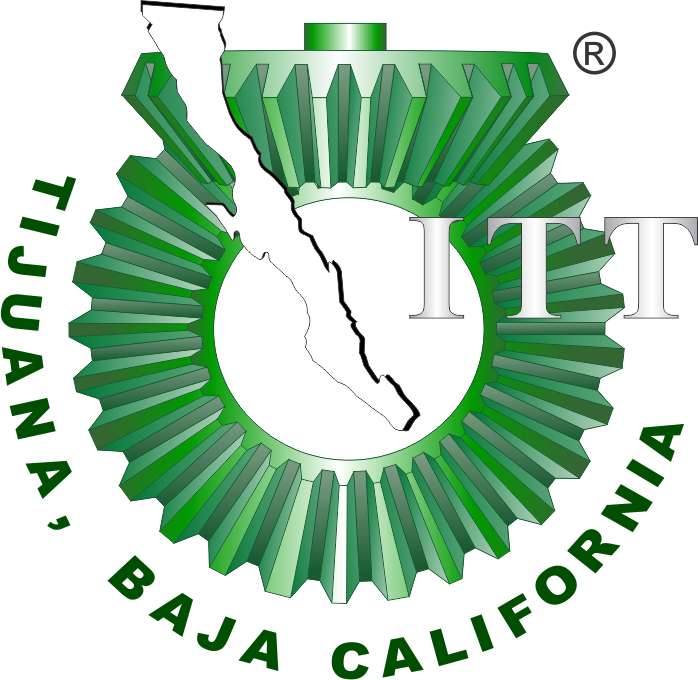

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

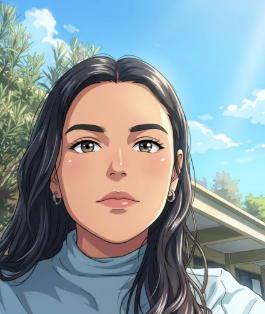

Nombre del alumno: **Gabriela Gissele Alvarez Garcia**

Número de control: **C22211520**

Correo institucional: **C22211520@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system("Sistema")
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';


## Respuesta al escalón

set_param('Sistema/S1','sw','1')
set_param('Sistema/Pao(t)','sw','1')
x1 = sim('Sistema', parameters)

x1 =   Simulink.SimulationOutput:

                     PA: [10045x1 double] 
                    PID: [10045x1 double] 
                    Pao: [10045x1 double] 
                      t: [10045x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


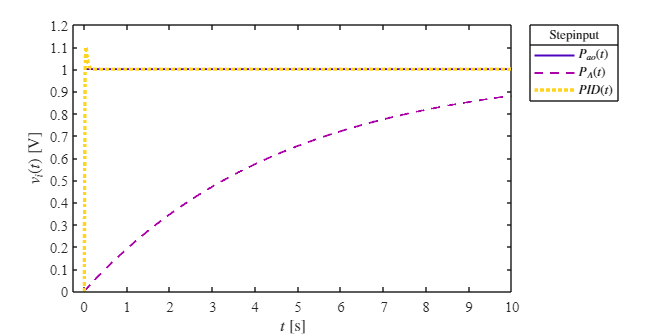

plotsignals(x1.t,x1.Pao,x1.PA,x1.PID,'Step')

## Respuesta al impulso

set_param('Sistema/S1','sw','0')
set_param('Sistema/Pao(t)','sw','1')
x2 = sim('Sistema', parameters)

x2 =   Simulink.SimulationOutput:

                     PA: [10075x1 double] 
                    PID: [10075x1 double] 
                    Pao: [10075x1 double] 
                      t: [10075x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


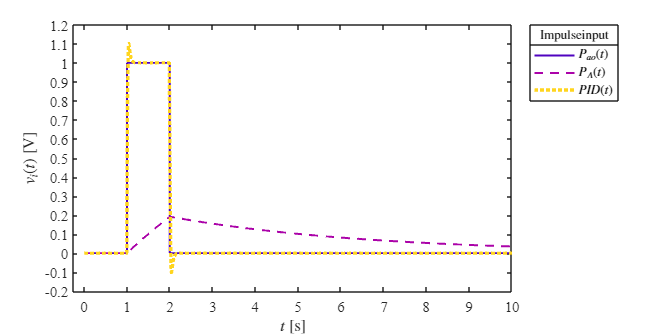

plotsignals(x2.t,x2.Pao,x2.PA,x2.PID,'Impulse')

## Respuesta a la rampa

set_param('Sistema/S2','sw','1')
set_param('Sistema/Pao(t)','sw','0')
x3 = sim('Sistema', parameters)

x3 =   Simulink.SimulationOutput:

                     PA: [10021x1 double] 
                    PID: [10021x1 double] 
                    Pao: [10021x1 double] 
                      t: [10021x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


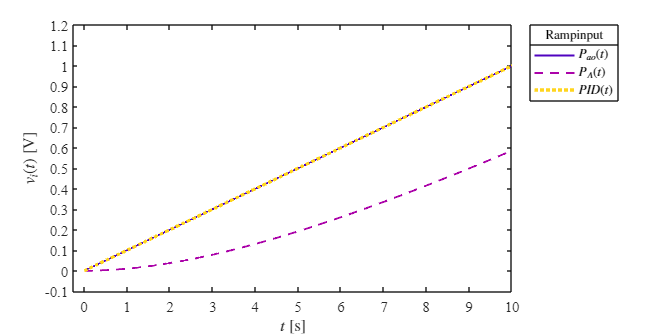

plotsignals(x3.t,x3.Pao,x3.PA,x3.PID,'Ramp')

## Respuesta a la función sinusoidal

set_param('Sistema/S2','sw','0')
set_param('Sistema/Pao(t)','sw','0')
x4 = sim('Sistema', parameters)

x4 =   Simulink.SimulationOutput:

                     PA: [10026x1 double] 
                    PID: [10026x1 double] 
                    Pao: [10026x1 double] 
                      t: [10026x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


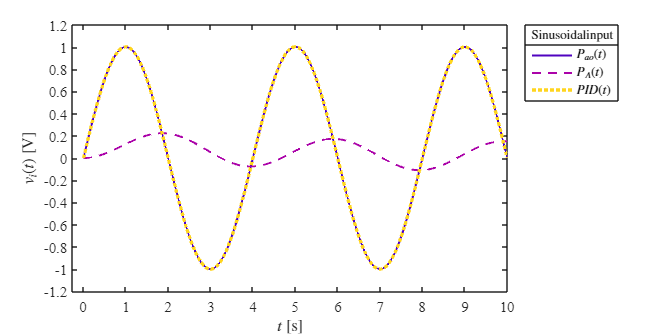

plotsignals(x4.t,x4.Pao,x4.PA,x4.PID,'Sinusoidal')

## **Función: Respuestas de la simulación**

function plotsignals(t,Pao,PA,PID,signal)
set(figure(), "color", 'w')
set(gcf, 'units', 'inches','position',[1,1,7,3.5])
set(gca, 'fontname', 'times new roman', 'fontsize', 11)
hold on; grid off, box on;
clr1 = [80,3,192]/255;
clr2 = [171,3,169]/255;
clr3 = [255,213,30]/255;
order = [clr1;clr2;clr3]; colororder(order)

plot(t,Pao,'-','LineWidth',1.5,'color',clr1)
plot(t,PA,'--','LineWidth',1.5,'Color',clr2)
plot(t,PID,':','LineWidth',2.5,'Color',clr3)
L = legend('$P_{ao}(t)$','$P_A(t)$','$PID(t)$');
set(L,'interpreter','latex','location','northeastoutside','orientation','vertical')
title(L,[signal,'input'])
xlabel('$t$ [s]','interpreter','latex')
ylabel('$v_i(t)$ [V]','Interpreter','latex')
xlim([-0.25 10]); xticks(0:1:10)

if signal == "Step"
    ylim([0 1.2]); yticks(0:0.1:1.2)
elseif signal == "Impulse"
    ylim([-0.2 1.2]); yticks(-0.2:0.1:1.2)
elseif signal == "Ramp"
    ylim([-0.1 1.2]); yticks(-0.1:0.1:1.2)
elseif signal == "Sinusoidal"
    ylim([-1.2 1.2]); yticks(-1.2:0.2:1.2)
end

exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end